data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1)

data = 832×173 table
       UID        iso2    iso3     code3    FIPS             Admin2             Province_State     Country_Region     Lat       Long_                 Combined_Key                 x1_22_20    x1_23_20    x1_24_20    x1_25_20    x1_26_20    x1_27_20    x1_28_20    x1_29_20    x1_30_20    x1_31_20    x2_1_20    x2_2_20    x2_3_20    x2_4_20    x2_5_20    x2_6_20    x2_7_20    x2_8_20    x2_9_20    x2_10_20    x2_11_20    x2_12


Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);
Total_Population = (Confounding.TOT_POP);

cases = table2array(data(:,12:173));
cases = cases./Total_Population;

[rC, cC] = size(cases);

splines = zeros(rC,1024);
derivatives = zeros(rC,1024);

for t = 1:rC
    casesS = cases(t,:);
    casesS = nonzeros(casesS); % non-zero cases 
    if length(casesS)>1
        x = [1:length(casesS)]';  % number of days since first case 
        f = fit(x, casesS, 'smoothingspline');
        xeval = linspace(1, length(casesS), 1024);
        sp_eval = f(xeval)';
        splines(t,:)= sp_eval;
        
        [fx, fxx] = differentiate(f, xeval);
        derivatives(t,:)=fx';
    end 
end 

derivatives1 = derivatives(:,[1:256]);
D1_m = mean(derivatives1,2);
derivatives2 = derivatives(:,[257:512]);
D2_m = mean(derivatives2,2);
derivatives3 = derivatives(:,[513:768]);
D3_m = mean(derivatives3,2);
derivatives4 = derivatives(:,[769:1024]);
D4_m = mean(derivatives4,2);

DSum = sum([abs(D1_m), abs(D2_m), abs(D3_m), abs(D4_m)],2);
D_mN = [abs(D1_m)./DSum, abs(D2_m)./DSum, abs(D3_m)./DSum, abs(D4_m)./DSum];

[b,idx] = sort(D_mN, 2, 'descend');
[rT, cT] = find(D_mN>0.80); % Finding curves with dominating spikes
for i = 1:length(rT)
    if cT(i)~=4
        idx(rT(i),:)=[1 2 3 4]; % will force classification as flattened
    else
        idx(rT(i),:)=[1 4 2 3]; % will force classification as resurged
    end
end 

diff_3_4 = abs(D_mN(:,3)-D_mN(:,4));
Bdiff_3_4 = diff_3_4>0.15;

lables_GT_F = [1 2 3 4; 1 3 2 4; 1 3 4 2; 2 1 3 4; 2 3 1 4; 2 3 4 1; 3 1 2 4; 3 1 4 2; 3 2 1 4; 3 2 4 1; 3 4 1 2; 3 4 2 1];
lables_LT_F = [1 2 3 4; 1 2 4 3; 1 3 2 4; 2 1 3 4; 2 1 4 3; 2 3 1 4; 2 3 4 1; 3 1 2 4; 3 2 1 4];

lables_GT_FR = [1 2 4 3; 1 4 2 3; 1 4 3 2; 2 4 1 3; 2 4 3 1; 4 1 2 3; 4 1 3 2; 4 2 1 3; 4 2 3 1];
lables_LT_FR = [1 4 2 3; 4 1 2 3; 4 1 3 2];

lables_GT_CS = [2 1 4 3; 4 3 1 2; 4 3 2 1];
lables_LT_CS = [1 3 4 2; 1 4 3 2; 2 4 1 3; 2 4 3 1; 3 1 4 2; 3 2 4 1; 3 4 1 2; 3 4 2 1; 4 2 1 3; 4 2 3 1; 4 3 1 2; 4 3 2 1];

descriptor = zeros(1,rC);
for i = 1:rC
    index = idx(i,:);
    if Bdiff_3_4(i)
        if nnz(ismember(index, lables_GT_F, 'rows'))~=0
            descriptor(i) = 1;
        elseif nnz(ismember(index, lables_GT_FR, 'rows'))~=0
            descriptor(i) = 2;
         elseif nnz(ismember(index, lables_GT_CS, 'rows'))~=0
            descriptor(i) = 3;
        end 
    else 
        if nnz(ismember(index, lables_LT_F, 'rows'))~=0
            descriptor(i) = 1;
        elseif nnz(ismember(index, lables_LT_FR, 'rows'))~=0
            descriptor(i) = 2;
         elseif nnz(ismember(index, lables_LT_CS, 'rows'))~=0
            descriptor(i) = 3;
        end
    end 
end 

v_Names = {'County', 'State', 'Combined_Key', 'Case_Curve_Class'}

v_Names = 1×4 cell array
    'County'    'State'    'Combined_Key'    'Case_Curve_Class'


Curve_Class = table(data.Admin2, data.Province_State, data.Combined_Key, descriptor', 'VariableNames', v_Names)

Curve_Class = 832×4 table
            County                 State                      Combined_Key                 Case_Curve_Class
    ______________________    ________________    _____________________________________    ________________

    'Baldwin'                 'Alabama'           'Baldwin, Alabama, US'                   2               
    'Colbert'                 'Alabama'           'Colbert, Alabama, US'                   3               
    'DeKalb'                  'Alabama'           'DeKalb, Alabama, US'                    2               
    'Etowah'                  'Alabama'           'Etowah, Alabama, US'                    2               
    'Houston'                 'Alabama'           'Houston, Alabama, US'                   3               
    'Jefferson'               'Alabama'           'Jefferson, Alabama, US'       


writetable(Curve_Class, '/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/Case_Curve_Class_D.csv')

clf;
i = 201; 

x = [1:1024];
figure(1)

subplot(3,1,1)
plot(x,splines(i,:))
xlim([0,1024])
grid on; 
title('Spline')

subplot(3,1,2)
plot(x,(derivatives(i,:)))
xlim([0,1024])
grid on; 
title('Derivative')

subplot(3,1,3)
X = categorical({'1st Quarter', '2nd Quarter', '3rd Quarter', '4th Quarter'});
X = reordercats(X,{'1st Quarter', '2nd Quarter', '3rd Quarter', '4th Quarter'});
Y = D_mN(i,:)

Y =     0.2599    0.4124    0.1984    0.1294


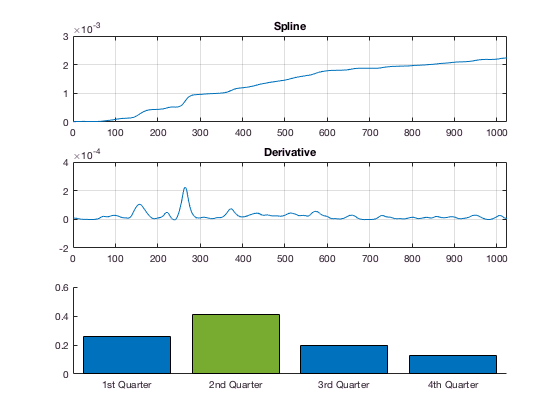

YM = zeros(size(Y));
[~, idxx] = max(Y);
YM(idxx) = Y(idxx);

hold on; 
bar(X,Y,'FaceColor',[0 0.4470 0.7410]);
bar(X, YM, 'FaceColor', [0.4660 0.6740 0.1880]);
hold off; 